# Utilizzo dei dati di sequenziamento di nuova generazione di Illumina/Solexa

In questo esempio viene illustrato come leggere ed eseguire operazioni di base con i dati prodotti da Illumina®/Solexa Genome Analyzer®.

## Introduzione

Durante un'analisi eseguita con il software Genome Analyzer Pipeline, Vengono prodotti diversi file intermedi. In questo esempio, imparerai Come leggere e manipolare le informazioni contenute nei file di sequenza (`_``sequence.txt`).

## Lettura di file _sequence.txt (FASTQ)

Il `_``sequence.txt` sono file in formato FASTQ che contengono le letture di sequenza e i loro punteggi di qualità, dopo il taglio di qualità e filtraggio.  L'output, `reads`, è una matrice di celle di strutture contenenti i seguenti campi: `Header`, `Sequence` e `Quality`.

filename = 'ilmnsolexa_sequence.txt';

È possibile utilizzare il comando `fastqinfo` per visualizzare un riepilogo di contenuti di un `_sequence.txt`

info = fastqinfo(filename)

A sua volta è possibile utilizzare `fastqread` funzione per leggere il contenuto del file `_sequence.txt`

reads = fastqread(filename)

Si consiglia di leggere il contenuto in blocchi usando il comando `blockread` dell'opzione `fastqread` funzione.

Assegnamo a `M` il valore 150 e ad `N` 260 tramite comando

M = 150;
N = info.NumberOfEntries;

La funzione `fastaread` restituisce i dati di sequenza dal `filename` di input come struttura

La funzione `blockread` specifica un vettore a due elementi [1 M] da leggere in un blocco di voci che iniziano dalla voce 1 e terminano alla voce M(150)

readsFirst = fastqread(filename, 'blockread', [1 M])
readsLast = fastqread(filename, 'blockread', [N-M+1, N])

Di seguito riporto un esempio della possibile struttura di un database basato sulle tabelle: `cromosomi, qualita, read e genoma` come da file, ma basato su dati e informazioni ricavate personalmente:

***Diagramma ER del database, costruito utilizzando App.diagrams.net ***:

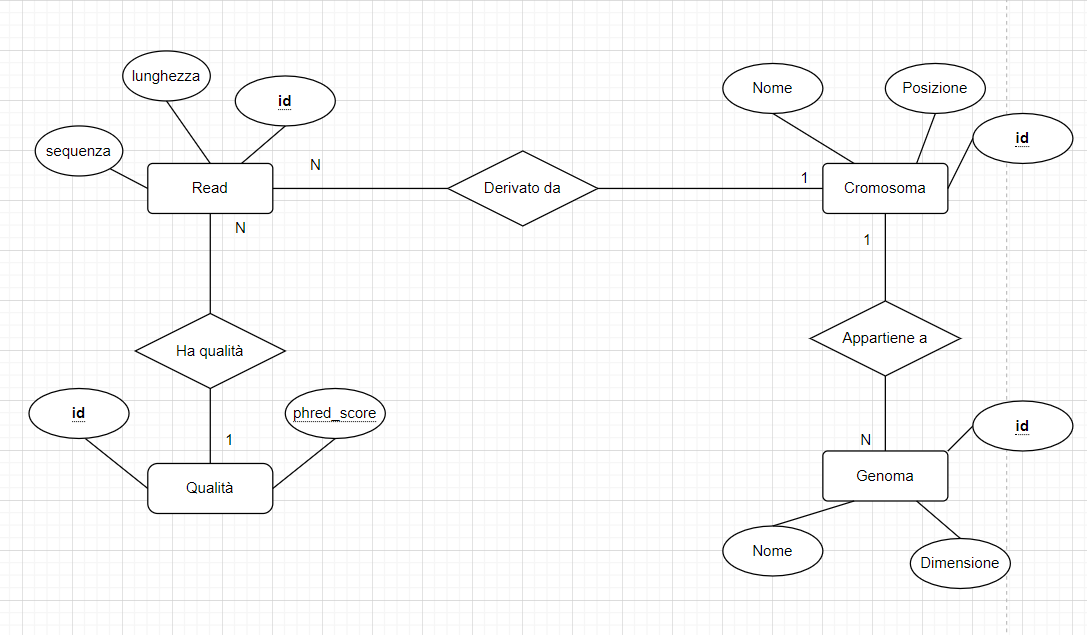

***Diagramma ER del database, costruito utilizzando Workbench MySQL:***

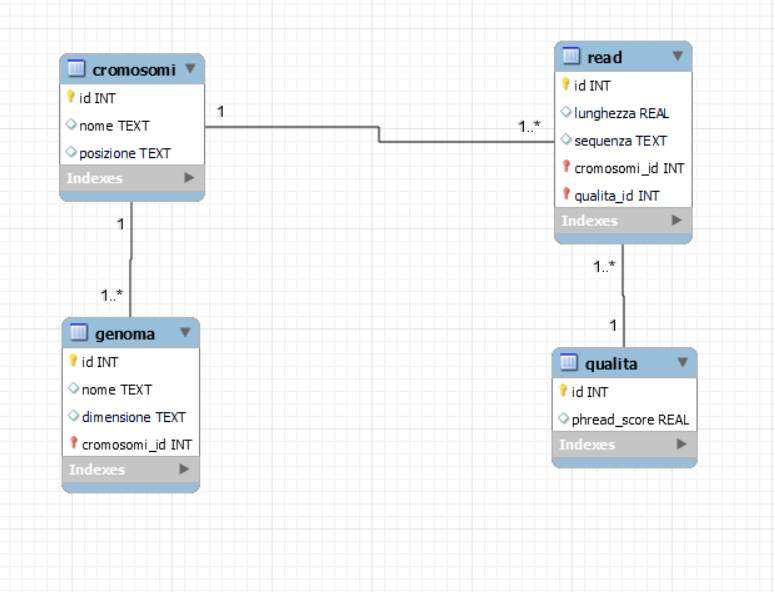

**Connessione al Database e creazioni delle table.**

Mi connetto al database SQLite (test_db) tramite comando sotto riportato:

dbfile = "C:\Users\munar\OneDrive\Documenti\MATLAB\Examples\R2023a\bioinfo\ilmnsolexademo\test_db.db";
conn = sqlite(dbfile);

Creo le tabelle 'cromosomi', 'qualita', 'read', 'genoma' con il comando 'create table' in cui pongo i diversi attributi dell'entità, oltre alla chiave d'accesso e definisco il tipo:

sqlquery="CREATE TABLE IF NOT EXISTS cromosomi (id INTEGER NOT NULL, nome TEXT, posizione TEXT, PRIMARY KEY(id AUTOINCREMENT))";
exec(conn, sqlquery);

sqlquery="CREATE TABLE IF NOT EXISTS qualita (id INTEGER NOT NULL, phred_score REAL, PRIMARY KEY(id AUTOINCREMENT))";
exec(conn, sqlquery);

sqlquery="CREATE TABLE IF NOT EXISTS read (id INTEGER NOT NULL, lunghezza REAL, sequenza TEXT, id_cromosoma INTEGER, id_qualita INTEGER, PRIMARY KEY(id AUTOINCREMENT), FOREIGN KEY(id_cromosoma) REFERENCES cromosomi(id), FOREIGN KEY(id_qualita) REFERENCES qualita(id))";
exec(conn, sqlquery);

sqlquery="CREATE TABLE IF NOT EXISTS genoma (id INTEGER NOT NULL, nome TEXT, dimensione TEXT,  id_cromosoma INTEGER, PRIMARY KEY(id AUTOINCREMENT), FOREIGN KEY(id_cromosoma) REFERENCES cromosomi(id))";
exec(conn, sqlquery);

**Opero sul database cromosomi.**

Inserisco all'interno della table cromosomi le informazioni che riguardano il nome dei cromosomi, il nome e la posizione, attraverso il comando *INSERT TO* che inserisce record nella table specificata; record è un insieme di dati, considerati come un'unica entità (riga della table), ed è formata da elementi (campi), ognuno dei quali è destinato ad accogliere un particolare tipo di dato. 

Nella colonna name inserisco il nome del cromosoma, mentre nella colonna posizione inserisco il riferimento alla posizione del cromosoma.

sqlquery="INSERT INTO cromosomi (nome, posizione) VALUES ('Cromosoma 1', '1-249,250,621');";
exec(conn, sqlquery);

sqlquery="INSERT INTO cromosomi (nome, posizione) VALUES ('Cromosoma 2', '248,956,423-492,077,302');";
exec(conn, sqlquery);

sqlquery="INSERT INTO cromosomi (nome, posizione) VALUES ('Cromosoma 3', '492,077,303-690,235,097');";
exec(conn, sqlquery);

sqlquery="INSERT INTO cromosomi (nome, posizione) VALUES ('Cromosoma 4', '690,235,098-881,626,700');";
exec(conn, sqlquery);

sqlquery="INSERT INTO cromosomi (nome, posizione) VALUES ('Cromosoma 5', '881,626,701-1,094,310,000');";
exec(conn, sqlquery);

**Opero sul database qualita.**

Inserisco all'interno della table qualita le informazioni che riguardano il phred_score, attraverso il comando *INSERT TO* che inserisce record nella table specificata; record è un insieme di dati, considerati come un'unica entità (riga della table), ed è formata da elementi (campi), ognuno dei quali è destinato ad accogliere un particolare tipo di dato. 

sqlquery="INSERT INTO qualita (phred_score) VALUES ('1%');";
exec(conn, sqlquery);

sqlquery="INSERT INTO qualita (phred_score) VALUES ('0,1%');";
exec(conn, sqlquery);

sqlquery="INSERT INTO qualita (phred_score) VALUES ('0,01%');";
exec(conn, sqlquery);

sqlquery="INSERT INTO qualita (phred_score) VALUES ('0,001%');";
exec(conn, sqlquery);

sqlquery="INSERT INTO qualita (phred_score) VALUES ('0,0001%');";
exec(conn, sqlquery);

**Opero sul database read.**

Inserisco all'interno della table read le informazioni che riguardano la lunghezza, la sequenza, l'id_cromosoma e l'id_qualita, attraverso il comando *INSERT TO* che inserisce record nella table specificata; record è un insieme di dati, considerati come un'unica entità (riga della table), ed è formata da elementi (campi), ognuno dei quali è destinato ad accogliere un particolare tipo di dato. 

sqlquery="INSERT INTO read (lunghezza, sequenza, id_cromosoma, id_qualita) VALUES ('50 basi', 'AGCTGATTACCGTGACCTAGGTACCGATCGTACCATGCTAGCATCGTGC', 1, 1);";
exec(conn, sqlquery);

sqlquery="INSERT INTO read (lunghezza, sequenza, id_cromosoma, id_qualita) VALUES ('30 basi', 'AGCTAGCTAGCTAGCTAGCTAGCTAGCTAGC', 2, 2);";
exec(conn, sqlquery);

sqlquery="INSERT INTO read (lunghezza, sequenza, id_cromosoma, id_qualita) VALUES ('40 basi', 'TCGATAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGC', 3, 3);";
exec(conn, sqlquery);

sqlquery="INSERT INTO read (lunghezza, sequenza, id_cromosoma, id_qualita) VALUES ('60 basi', 'AGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCT', 4, 4);";
exec(conn, sqlquery);

sqlquery="INSERT INTO read (lunghezza, sequenza, id_cromosoma, id_qualita) VALUES ('70 basi', 'TCGATAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAGCTAG', 5, 5);";
exec(conn, sqlquery);

**Opero sul database genoma.**

Inserisco all'interno della table read le informazioni che riguardano il nome, la posizione e l'id_cromosoma attraverso il comando *INSERT TO* che inserisce record nella table specificata; record è un insieme di dati, considerati come un'unica entità (riga della table), ed è formata da elementi (campi), ognuno dei quali è destinato ad accogliere un particolare tipo di dato. 

sqlquery="INSERT INTO genoma (nome, dimensione, id_cromosoma) VALUES ('Genoma di E. coli', '4,642,073 basi', 1);";
exec(conn, sqlquery);

sqlquery="INSERT INTO genoma (nome, dimensione, id_cromosoma) VALUES ('Genoma di Saccharomyces cerevisiae', '12.1 milioni di basi', 2);";
exec(conn, sqlquery);

sqlquery="INSERT INTO genoma (nome, dimensione, id_cromosoma) VALUES ('Genoma di Drosophila melanogaster', '143.7 milioni di basi', 3);";
exec(conn, sqlquery);

sqlquery="INSERT INTO genoma (nome, dimensione, id_cromosoma) VALUES ('Genoma di Mus musculus', '2.7 miliardi di basi', 4);";
exec(conn, sqlquery);

sqlquery="INSERT INTO genoma (nome, dimensione, id_cromosoma) VALUES ('Genoma di Homo sapiens', '3.2 miliardi di basi', 5);";
exec(conn, sqlquery);

Creo un *select *per visualizzare la table 'nome_tabella' del database. In questo caso, utilizzo un widget per non ripetere lo stesso codice più volte

%insersci il nome della tabella di cui visualizzare i dati
nome_tabella = "genoma";
sqlquery="SELECT * FROM '"+nome_tabella+"';";
results = fetch(conn, sqlquery);
disp(results);

Ricavo un informazione da un campo specifico della table:

%inserisci il nome del genoma che vuoi ricercare
nome_genoma = "Genoma di E. coli";
sqlquery="select * FROM genoma WHERE nome='"+nome_genoma+"'";
results = fetch(conn, sqlquery);
disp(results);

Utilizzo la funzione `fetch` per interrogare il DB

%inserisci il nome del cromosoma che vuoi ricercare
nome_cromosoma = "cromosoma 2";
sqlquery="select * FROM cromosomi WHERE nome='"+nome_cromosoma+"'";
results = fetch(conn, sqlquery);
disp(results);

%inserisci la lunghezza del read che vuoi ricercare
nome_read = "40 basi";
sqlquery="select * FROM read WHERE lunghezza='"+nome_read+"'";
results = fetch(conn, sqlquery);
disp(results);

%inserisci il phred_score che vuoi ricercare
nome_qualita = "0,01%";
sqlquery="select * FROM qualita WHERE phred_score='"+nome_qualita+"'";
results = fetch(conn, sqlquery);
disp(results);

## Rilevamento della distribuzione della lunghezza delle letture di sequenza

Una volta caricate le informazioni sulla sequenza nell'area di lavoro, si può determinare il numero e la lunghezza della sequenza lette e tracciare la loro distribuzione come segue:

Accediamo alla matrice di celle di strutture `reads` e in particolare nel campo `sequence `ponendola in una variabile

seqs = {reads.Sequence};

La funzione `cellfun` applica una funzione a ogni elemento in una matrice di celle

readsLen = cellfun(@length, seqs);

La funzione `figure()` crea una nuova finestra della figura utilizzando i valori delle proprietà predefinite

figure();

La funzione` hist()` crea un istogramma a barre degli elementi in readsLen

hist(readsLen);

Intestazione dell'asse delle x

xlabel('Number of bases');

Intestazione dell'asse delle y

ylabel('Number of sequence reads');

Ecco il titolo del grafico

title('Length distribution of sequence reads')

## Rilevamento della composizione di base della sequenza

È inoltre possibile esaminare la composizione nucleotidica rilevando il numero delle occorrenze di ciascun tipo di base 'A', 'C', 'G', 'T' in ogni sequenza letta, come mostrato di seguito:

nt = {'A', 'C', 'G', 'T'};

nt corrisponde ad un cell array di caratteri

pos = cell(4,N);

`cell()` è una funzione che contiene dati, in questo caso 4 e N

for i = 1:4
    pos(i,:) = strfind(seqs, nt{i});
end

`strfind` cerca nella stringa, `seqs`, le occorrenze di una stringa più corta, `nt{i}`, restituendo l'indice iniziale di ciascuna di tali occorrenze nella matrice,` pos`

count = zeros(4,N);
for i = 1:4
    count(i,:) = cellfun(@length, pos(i,:));
end

`for` è una funzione che permette di fare un ciclo

figure();
subplot(2,2,1); hist(count(1,:)); title('A'); xlabel('Occurrences'); ylabel('Number of sequence reads');
subplot(2,2,2); hist(count(2,:)); title('C'); xlabel('Occurrences'); ylabel('Number of sequence reads');
subplot(2,2,3); hist(count(3,:)); title('G'); xlabel('Occurrences'); ylabel('Number of sequence reads');
subplot(2,2,4); hist(count(4,:)); title('T'); xlabel('Occurrences'); ylabel('Number of sequence reads');

funzioni già descritte nel grafico precedente

`subplot` è una funzione che divide la figura corrente in riquadri rettangolari numerati per riga.

figure(); hist(count');
xlabel('Occurrences');
ylabel('Number of sequence reads');
legend('A', 'C', 'G', 'T');
title('Base distribution by nucleotide type');

funzioni già descritte nel grafico precedente

## Indagine sulla distribuzione del punteggio di qualità

Ogni sequenza letta nella casella `_``sequence.txt` è associata a un punteggio. Il punteggio è definito come SQ = -10 * log10 (p / (1-p)), dove p è la probabilità di errore di una base. È possibile esaminare i punteggi di qualità associati alle chiamate di base convertendo il formato ASCII in un rappresentazione numerica e quindi tracciare la loro distribuzione, come mostrato sotto:

Accediamo alla matrice di celle di strutture `reads` e in particolare nel campo `quality `ponendola in una variabile

sq = {reads.Quality}; % in formato ASCII
SQ = cellfun(@(x) double(x)-64, {reads.Quality}, 'UniformOutput', false); % in formato intero

Deviazione media, mediana e standard

avgSQ = cellfun(@mean, SQ);
medSQ = cellfun(@median, SQ);
stdSQ = cellfun(@std, SQ);

Distribuzione del grafico della qualità mediana e media

figure();
subplot(1,2,1); hist(medSQ);
xlabel('Median Score SQ');
ylabel('Number of sequence reads');
subplot(1,2,2); boxplot(avgSQ); ylabel('Average Score SQ');

funzioni già descritte nel grafico precedente

## Conversione dei punteggi di qualità tra standard

I punteggi di qualità trovati nei file Solexa/Illumina sono asintotici, ma non identici ai punteggi di qualità utilizzati nello standard Sanger (Phred-like punteggi, Q). Q è definito come -10 * log10 (p), dove p è l'errore probabilità di una base 'A', 'C', 'G', 'T'. Mentre i punteggi di qualità Phred sono numeri interi positivi, nella qualità Solexa/Illumina i punteggi possono essere negativi. Possiamo convertire i punteggi di qualità Solexa in Phred di punteggi di qualità utilizzando il seguente codice:

convertire da Solexa a Sanger standard

Q = cellfun(@(x) floor(.499 + 10 * log10(1+ 10 .^ (x/10))), SQ, ...
    'UniformOutput', false); % in formato intero
q = cellfun(@(x) char(x+33), Q, 'UniformOutput', false); % in formato ASCII

sanger = q(1:3)'
solexa = sq(1:3)'

## Filtraggio e mascheramento in base ai punteggi di qualità

Il filtraggio della purezza del segnale è già stato applicato alle sequenze nella `_``sequence.txt` ﬁle. È possibile eseguire filtri aggiuntivi, ad esempio considerando solo quelle letture di sequenza le cui basi hanno tutte le qualità di punteggi superiori a una determinata soglia:

**Qualità superiore alla soglia**

letture di sequenza le cui basi hanno tutte una qualità superiore alla soglia

len = 36;
qt = 10; % Soglia minima di qualità
a = cellfun(@(x) x > qt, SQ, 'UniformOutput', false);
b = cellfun(@sum, a);
c1 = find(b == len);

Numero di letture di sequenza che passano il filtro:

n1= numel(c1); 

`disp` visualizza il valore di cio nelle () senza stampare il nome del valore, in questo caso stampa che vi sono `n1 letture di sequenza aventi tutte le basi sopra la soglia qt (`n1 e qt vengono sostituiti dai valori`)`

disp([num2str(n1) ' sequence reads have all bases above threshold ' num2str(qt)]);

In alternativa, è possibile considerare solo le letture di sequenza che hanno meno di un dato numero di basi con punteggi di qualità inferiori alla soglia:

**Qualità inferiore alla soglia**

Letture di sequenza aventi basi inferiori a M con qualità inferiore alla soglia

Numero massimo di basi di scarsa qualità:

M = 5; 
a = cellfun(@(x) x <= qt, SQ, 'UniformOutput', false);
b = cellfun(@sum, a);
c2 = find(b <= M);

Numero di letture di sequenza che passano il filtro:

n2 = numel(c2); 

`numel()` restituisce il numero di elementi, numUnique, nella matrice uReads, equivalente a PROD

Il tutto viene stampato a schermo come prima:

disp([num2str(n2) ' sequence reads have less than ' num2str(M) ' bases below threshold ' num2str(qt)]);

Infine, è possibile applicare una maschera minuscola a quelle basi che hanno punteggi di qualità al di sotto della soglia:

**Maschera alle basi di qualità inferiore alla soglia**

seq = reads(1).Sequence
mseq = seq;
qt2 = 20;  % Soglia di qualità
mask = SQ{1} < qt2;
mseq(mask) = lower(seq(mask))

`lower()` converte i caratteri maiuscoli nella stringa (seq(mask)) nei caratteri minuscoli corrispondenti.